Jm=2e-2;
Jc=4e-2;

k=1000;
h=.2;
hm=.01;

A=[0 0 1 0;
    0 0 0 1;
    -k/Jm k/Jm -h/Jm-hm/Jm h/Jm;
    k/Jc -k/Jc h/Jc -h/Jc];
B=[0 0 ;
    0 0;
    1/Jm 0;
    0 1/Jc];
C=eye(4);
D=zeros(4,2);

model=ss(A,B,C,D);

sys_tf = tf(model);

tf1 = minreal(zpk(sys_tf(3,1)))

tf1 =
 
        50 (s^2 + 5s + 2.5e04)
  ----------------------------------
  (s+0.1667) (s^2 + 15.33s + 7.5e04)
 
Continuous-time zero/pole/gain model.



tf2 = minreal(zpk(sys_tf(4,1)))

tf2 =
 
             250 (s+5000)
  ----------------------------------
  (s+0.1667) (s^2 + 15.33s + 7.5e04)
 
Continuous-time zero/pole/gain model.



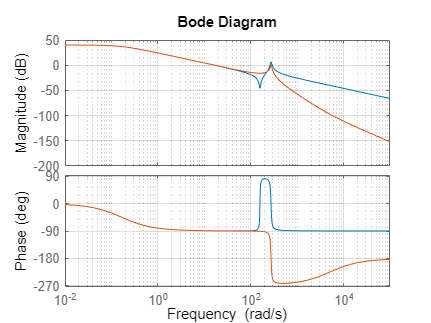


figure
bode(tf1)
hold on
bode(tf2)